# Part-II 探究CRC

## 误码图案与误块图案(利用已有数据直接绘图)

根据CRC统计的原理, 其只可能漏判, 不可能错判(不会将正确的判为错误的)

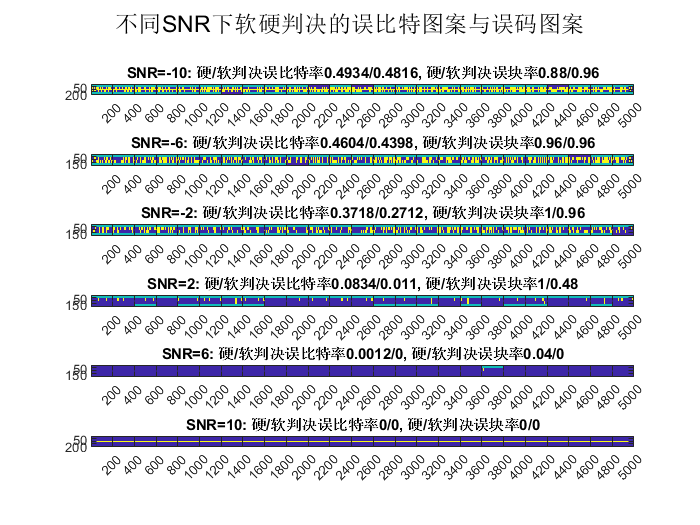

clear all, close all, clc
% 载入数据
data = load("Data\data_CRC.mat");
errimg_h = data.errimg_h;
errimg_s = data.errimg_s;
bulkimg_h = data.bulkimg_h;
bulkimg_s = data.bulkimg_s;
BER = data.BER;
len = data.N;
snr_dB = data.snr_dB;

num = size(snr_dB,2);

wid = 50;
for i=1:num
    img_bits_h = repmat(errimg_h(i,:), [wid 1]);
    img_bits_s = repmat(errimg_s(i,:), [wid 1]);
    img_bulk_h = repmat(bulkimg_h(i,:), [wid 1]);
    img_bulk_s = repmat(bulkimg_s(i,:), [wid 1]);
    img = [img_bulk_h; img_bits_h; 255*ones(10,len); img_bits_s; img_bulk_s];
    subplot(num, 1, i);
    image(img);
    ax = gca;
    ax.XTick = 200:200:len;
    title("SNR="+num2str(snr_dB(i))+": 硬/软判决误比特率"+num2str(BER(1,i))+"/"+num2str(BER(2,i))+", 硬/软判决误块率"+num2str(BER(3,i))+"/"+num2str(BER(4,i)));
end
sgtitle("不同SNR下软硬判决的误比特图案与误码图案");

## 函数CRC与crc_judge功能验证

N = 1000;
x = randi(2, 1, N)-1;
y = CRC(x);
r = y;
[org, wrg, idx] = crc_judge(r)

org =      1     0     1     0     0     0     0     0     0     1     1     1     0     0     0     1     0     0     1     1     1     0     0     1     1     0     0     1     0     0     1     1     1     1     1     0     1     0     1     1     0     0     0     0     1     1     1     0     0     1


wrg = 0

idx =
     []


r(1:4) = mod(r(1:4)+1, 2);
[org, wrg, idx] = crc_judge(r)

org =      0     1     0     1     0     0     0     0     0     1     1     1     0     0     0     1     0     0     1     1     1     0     0     1     1     0     0     1     0     0     1     1     1     1     1     0     1     0     1     1     0     0     0     0     1     1     1     0     0     1


wrg = 0

idx =
     []


# 完整模块

## 数据生成与参数确定

clear all, close all, clc

% 传输数据
N = 5000;               % 传输量5000--CRC-->5400--1/2收尾卷积-->5402--约定丢弃2bits-->5400
x = randi(2, 1, N)-1;   % 待传输的原始信息
% 映射系数的调控
T=5;
mbit = 2;
snr_low = -10;          % snr最低值(dB)
snr_high = 10;          % snr最高值(dB)
snr_step = 4;           % snr步长
% 卷积矩阵
A_2 = [1 1 0 1          % 1/2效率
     1 1 1 1]';
% 映射矩阵
Mmap2 = [ -1 -1;    -1  1;    1 -1;    1  1 ];

## 添加CRC

每200bits添加16bits校验位, 即添加CRC

crc_code = CRC(x);      % 默认: k=200, gx=[1 1 0 0, 0 0 0 0, 0 0 0 1, 0 0 0 1]

## 编码,映射,信道,解映射,译码,CRC统计误块率

软判决译码不需要预先解映射, 硬判决译码需要预先解映射

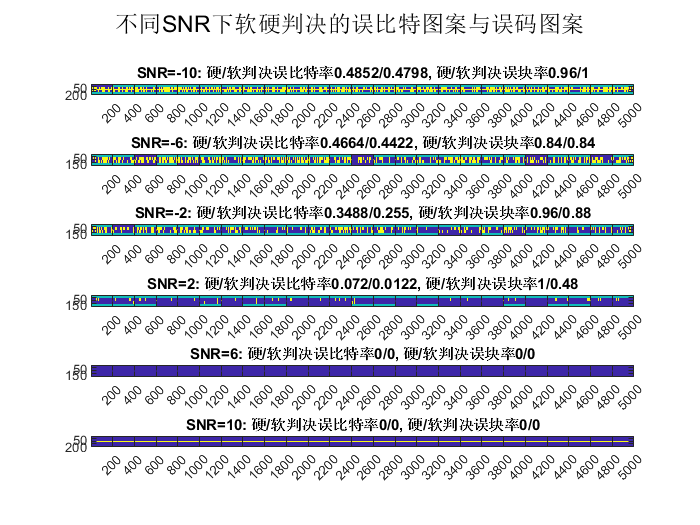

% 映射前的过程与snr无关
snr_dB = snr_low:snr_step:snr_high;     % SNR取值集
BER = repmat(snr_dB*0, [4 1]);          % 误码率和误块率记录矩阵: 1,2为误码率,3,4为误块率
errimg_h = repmat(x*0, [10 1]);         % 误码位置记录(硬判决)
errimg_s = repmat(x*0, [10 1]);         % 误码位置记录(软判决)
bulkimg_h = repmat(x*0, [10 1]);    % 误块位置记录(硬判决)
bulkimg_s = repmat(x*0, [10 1]);    % 误块位置记录(软判决)

for i=1:length(snr_dB)
    % 映射参数按照snr与mbit进行配置
    snr = 10^(snr_dB(i)/10);
    Mmap = sqrt(snr/2)*Mmap2;
    % 1/2效率收尾卷积编码及2-bit映射
    L = N;
    u = mapping(conv_encode(crc_code, A_2, 1), 0, 2, Mmap);
    v = channel(u, T, size(u, 2));
    bits = mapping(v, 1, 2, Mmap);
    h = viterbi(bits, A_2, 1, "hard", Mmap);
    s = viterbi(v, A_2, 1, "soft", Mmap);
    % 解CRC并统计误块率
    [rh, eh, eh_bulk] = crc_judge(h);
    [rs, es, es_bulk] = crc_judge(s);
    % 绘制误块图案与误码图案
    errh = find(rh-x);
    errs = find(rs-x);
    errimg_h(i,errh) = 255;
    errimg_s(i,errs) = 255;
    bulkimg_h(i, eh_bulk) = 128;
    bulkimg_s(i, es_bulk) = 128;
    BER(1,i) = size(errh,2)/N;
    BER(2,i) = size(errs,2)/N;
    BER(3,i) = eh;
    BER(4,i) = es;
end
% 存储数据
save("Data\data_CRC_new.mat", "errimg_h", "errimg_s", "bulkimg_h", "bulkimg_s", "BER", "N", "snr_dB");

len = N;
num = size(snr_dB,2);

wid = 50;
for i=1:num
    img_bits_h = repmat(errimg_h(i,:), [wid 1]);
    img_bits_s = repmat(errimg_s(i,:), [wid 1]);
    img_bulk_h = repmat(bulkimg_h(i,:), [wid 1]);
    img_bulk_s = repmat(bulkimg_s(i,:), [wid 1]);
    img = [img_bulk_h; img_bits_h; 255*ones(10,len); img_bits_s; img_bulk_s];
    subplot(num, 1, i);
    image(img);
    ax = gca;
    ax.XTick = 200:200:len;
    title("SNR="+num2str(snr_dB(i))+": 硬/软判决误比特率"+num2str(BER(1,i))+"/"+num2str(BER(2,i))+", 硬/软判决误块率"+num2str(BER(3,i))+"/"+num2str(BER(4,i)));
end
sgtitle("不同SNR下软硬判决的误比特图案与误码图案");